# Spline demo

Test spline for the function $f:[-1,1]\rightarrow\mathbb{R}$, $f(x)=x^2\sin(2\pi x)$.

This test computes the complete, D2 class, natural, and deBoor splines for the given function.

close all

Define function and its derivatives

f = @(x) x.^2.*sin(2*pi*x);
fd = @(x) 2*x.*sin(2*pi*x) + 2*x.^2*pi.*cos(2*pi*x);
fdd = @(x) 2*sin(2*pi*x) - 4*x.^2*pi^2.*sin(2*pi*x) + 8*x*pi.*cos(2*pi*x);

The nodes are Chebyshev #2 points, i.e $x_k =\cos \frac{k}{m}\pi$, $k=0,\dots,m$. 

t=linspace(-1,1,200);
m=9;
k=0:m;
x=sort(cos(k*pi/m));
y=f(x);
fd1=fd([-1,1]);
fd2=fdd([-1,1]);
cc1=CubicSplinec(x,y,0,fd1);
cc2=CubicSplinec(x,y,1,fd2);
cc3=CubicSplinec(x,y,2);
cc4=CubicSplinec(x,y,3);
z1=evalsplinec(x,cc1,t);
z2=evalsplinec(x,cc2,t);
z3=evalsplinec(x,cc3,t);
z4=evalsplinec(x,cc4,t);
ft=f(t');

Plotting

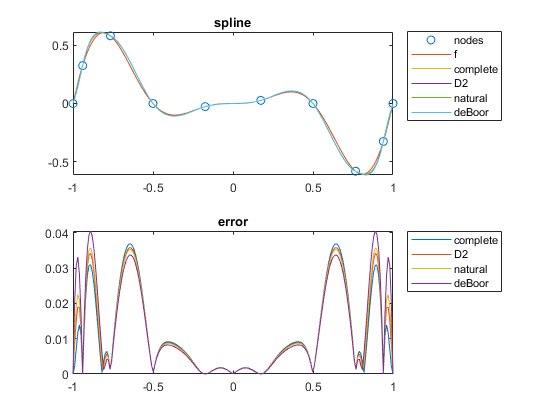

figure(1)
subplot(2,1,1)
plot(x,y,'o',t,f(t),t,[z1,z2,z3,z4])
legend('nodes','f','complete','D2','natural','deBoor','Location','bestoutside');
title('spline')
subplot(2,1,2)
plot(t',abs(repmat(ft,1,4)-[z1,z2,z3,z4]))
legend('complete','D2','natural','deBoor','Location','bestoutside');
title('error')

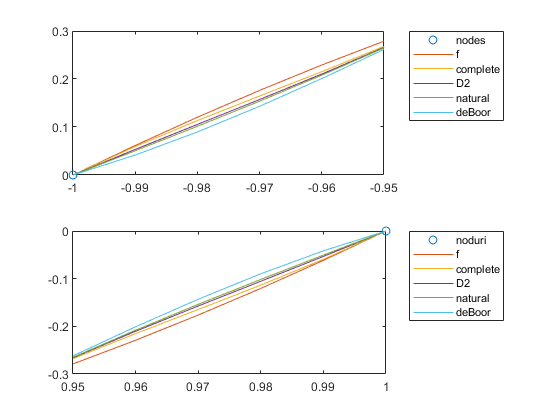


figure(2)
subplot(2,1,1)
plot(x,y,'o',t,f(t),t,[z1,z2,z3,z4])
legend('nodes','f','complete','D2','natural','deBoor','Location','bestoutside');
xlim([-1,-0.95])
subplot(2,1,2)
plot(x,y,'o',t,f(t),t,[z1,z2,z3,z4])
legend('noduri','f','complete','D2','natural','deBoor','Location','bestoutside');
xlim([0.95,1])